# Three-body problem (/^▽^)/

For once, I'll have to use Sauer's code since I don't quite have time to write my own...

## CP10

la la la

## CP11

da da da

         0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500
    0.5000
    0.5500
    0.6000
    0.6500
    0.7000
    0.7500
    0.8000
    0.8500
    0.9000
    0.9500
    1.0000
    1.0500
    1.1000
    1.1500
    1.2000
    1.2500
    1.3000
    1.3500
    1.4000
    1.4500
    1.5000
    1.5500
    1.6000
    1.6500
    1.7000
    1.7500
    1.8000
    1.8500
    1.9000
    1.9500
    2.0000
    2.0500
    2.1000
    2.1500
    2.2000
    2.2500
    2.3000
    2.3500
    2.4000
    2.4500
    2.5000
    2.5500
    2.6000
    2.6500
    2.7000
    2.7500
    2.8000
    2.8500
    2.9000
    2.9500
    3.0000
    3.0500
    3.1000
    3.1500
    3.2000
    3.2500
    3.3000
    3.3500
    3.4000
    3.4500
    3.5000
    3.5500
    3.6000
    3.6500
    3.7000
    3.7500
    3.8000
    3.8500
    3.9000
    3.9500
    4.0000
    4.0500
    4.1000
    4.1500
    4.2000
    4.2500
    4.3000
    4.3500
    4.4000
    4.4500
    4.5000

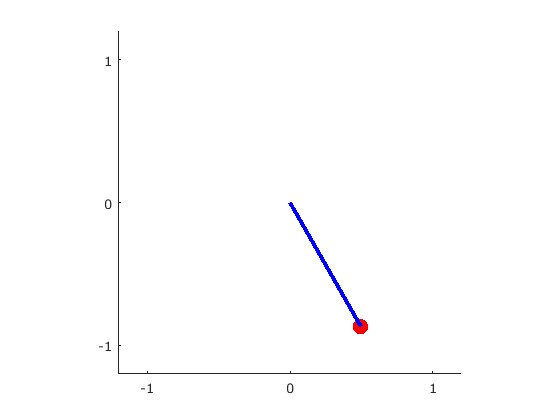

% code here
%pend([0 10],[pi/2 0],200,trapezoid,sloppy)
% okay, I do *not* understand function passing in Matlab
pend([0 10],[pi/2 0],200, ...
    @(t,y,h,f) trapezoid(t,y,h,f), ...
    @(t,y) pendulum(t,y))

Magnificent code:

function pend(interval, intialConds, n, step, slope)
% Program 6.3 Animation program for pendulum
% Inputs: time interval inter,
%         initial values ic=[y(1,1) y(1,2)],
%         number of steps n
% Calls a one-step method such as trapstep.m
% Example usage: pend([0 10],[pi/2 0],200)
    a = interval(1);
    b = interval(2);
    h = (b - a)/n;
    y(1,:) = intialConds;
    t = linspace(a,b,n+1)';
    t(1) = a;
    disp(t)
    
    set(gca, 'xlim', [-1.2 1.2], 'ylim', [-1.2 1.2], ...
        'XTick', [-1 0 1], 'YTick', [-1 0 1], ...
        'Drawmode', 'fast', 'Visible', 'on', 'NextPlot', 'add')
    
    cla;
    axis square
    
    % make aspect ratio 1 - 1
    bob=line('color','r','Marker','.','markersize',40, ...
             'erase','xor','xdata',[],'ydata',[]);
    rod=line('color','b','LineStyle','-','LineWidth',3, ...
             'erase','xor','xdata',[],'ydata',[]);
    
    % Do actual iteration, while drawing
    for k=1:n
        %t(k+1) = t(k)+h;
        y(k+1,:) = step(t(k), y(k,:), h, slope);
        
        % this seems rather specific
        xbob=sin(y(k+1,1));
        ybob= -cos(y(k+1,1));
        xrod=[0 xbob]; yrod=[0 ybob];
        
        set(rod,'xdata',xrod,'ydata',yrod)
        set(bob,'xdata',xbob,'ydata',ybob)
        drawnow;
        pause(h)
    end
end

% Standard trapezoid step
function y=trapezoid(t, y, h, slope)
    s1 = slope(t, y);
    s2 = slope(t+h, y + h*s1);
    y = y + h*(s1+s2)/2;
end

% from the example
function z=pendulum(~,y)
    g=9.81;length=1;
    z(1)=y(2);
    z(2)=-(g/length)*sin(y(1));
end